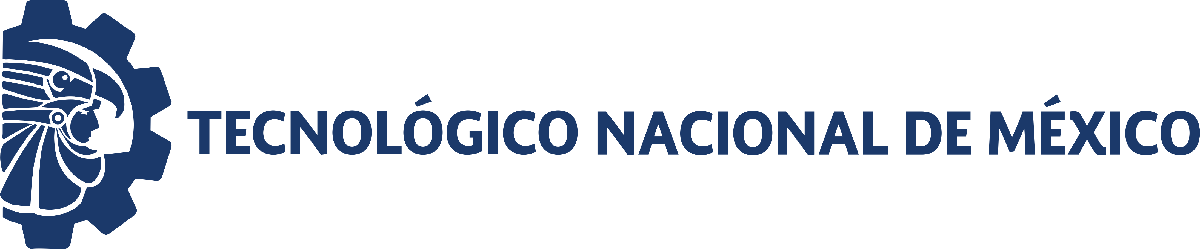                                 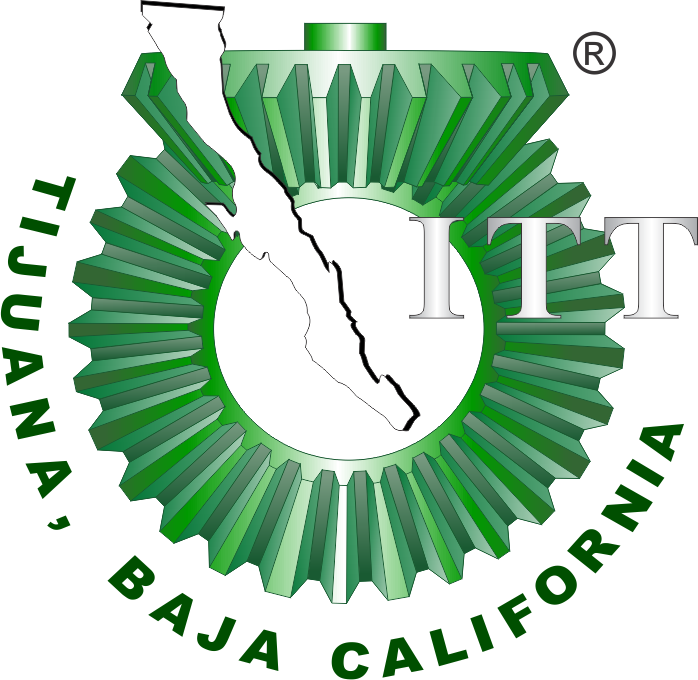

# Práctica tres: Sistema Endocrino

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

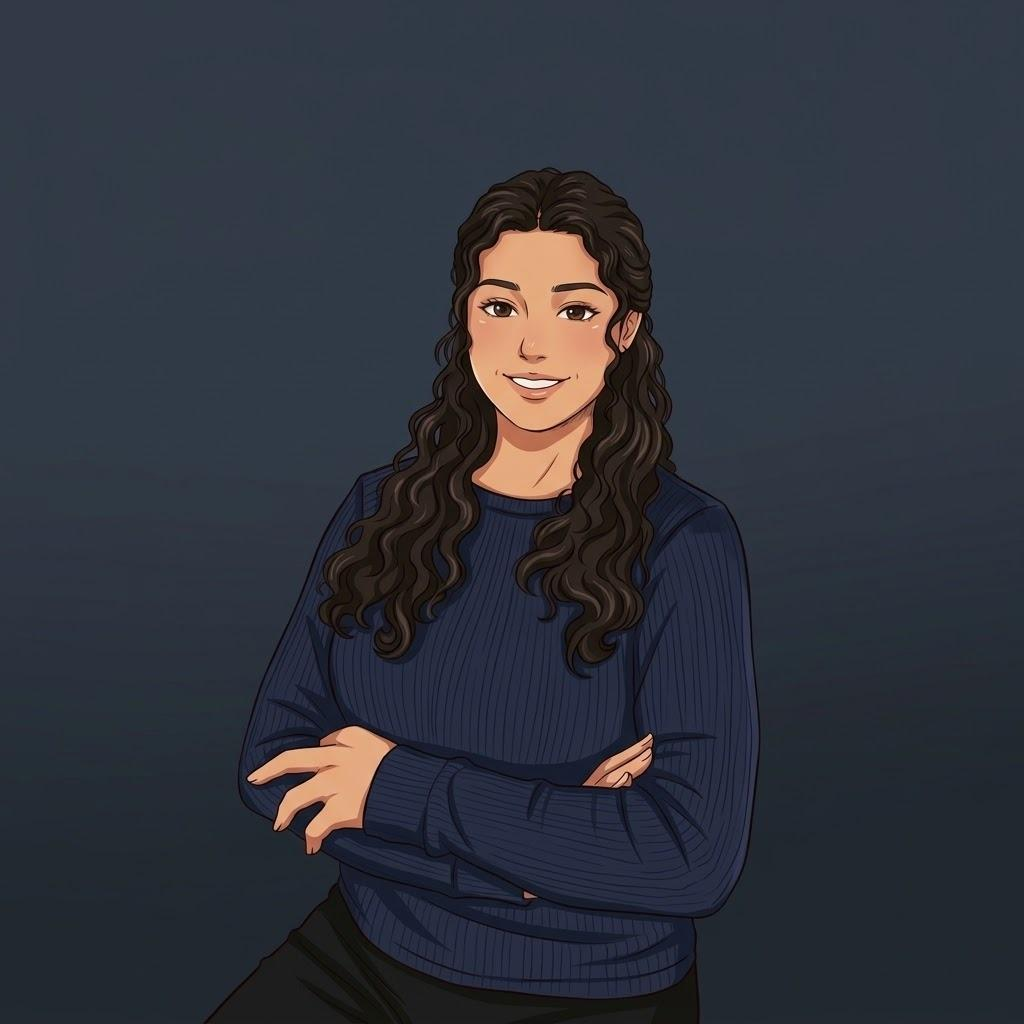

Nombre del alumno: Alexa Montaño Gomez

Número de control: 23212215

Correo institucional: l23212215**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('Practica_Endocrino')
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
x = sim('Practica_Endocrino',parameters);

##     Respuesta al impulso unitario

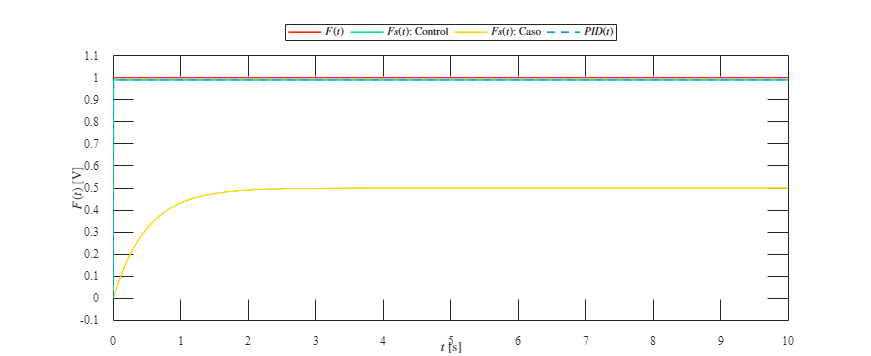

plotsignals(x.t,x.Ve,x.Fsx,x.Fsy,x.PID,'Control y caso')

## Funcion: Respuesta de la simulacion

function plotsignals(t,s,s1,s2,s3,signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,11,4.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = [255, 38, 0] / 255;   
    clr2 = [0, 230, 118] / 255;  
    clr3 = [255, 214, 10] / 255;  
    clr4 = [0, 145, 255] / 255;  
    order = [clr1;clr2;clr3;clr4]; colororder(order)

    if signal == "Control y caso"
        plot(t,s,'-',t,s1,'-',t,s2,'-',t,s3,'--', ...
            'LineWidth',1.5,'MarkerSize',5, ...
            'MarkerIndices',1:1e3:length(t));
        l = legend('$F(t)$','$Fs(t)$: Control', ...
            '$Fs(t)$: Caso','$PID(t)$');
    end

    set(l,'interpreter','latex','location','northoutside','orientation','horizontal')

    xlabel('$t$ [s]','interpreter','latex')
    ylabel('$F(t)$ [V]','interpreter','latex')

    xlim([0 10]); xticks(0:1:15)
    ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)

    exportgraphics(gcf,[signal,'.matlab.pdf'],'contenttype','vector')
end